## **Table of Content**

- **Data Read in**

###     Starting from Raw Received Value:

- **Raw received value to Transmitted Codeword Metric: Simulation vs. Theoretical**

- **Raw received value to Decoded Codeword Listsize vs. RRV to Transmitted Codeword Metric**

- **Raw received value to Decoded Codeword Listsize vs. RRV to Decoded Codeword Metric**

###     Starting from Projected Received Value:

- **Projected received value to Transmitted Codeword Metric: Simulation vs. Theoretical**

- **Projected received value to Decoded Codeword Listsize vs. PRV to Transmitted Codeword Metric**

- **Projected received value to Decoded Codeword Listsize vs. PRV to Decoded Codeword Metric**

## **Data Read-In**

%% Rundundancy, systematic symbols theoretical PDF
% Comparing with collected data
close all;
clear;
clc;

% Raw Received Value
RRVtoTransmitted_Metric = load("../output/RRV/transmitted_metric.txt");
RRVtoDecoded_Metric     = load("../output/RRV/decoded_metric.txt");
RRVtoDecoded_Listsize   = load("../output/RRV/decoded_listsize.txt");
RRVtoDecoded_Type       = load("../output/RRV/decoded_type.txt");

% Projected Received Value
PRVtoTransmitted_Metric = load("../output/PRV/transmitted_metric.txt");
PRVtoDecoded_Metric     = load("../output/PRV/decoded_metric.txt");
PRVtoDecoded_Listsize   = load("../output/PRV/decoded_listsize.txt");
PRVtoDecoded_Type       = load("../output/PRV/decoded_type.txt");


## **Raw received value to Transmitted Codeword Metric: Simulation vs. Theoretical**

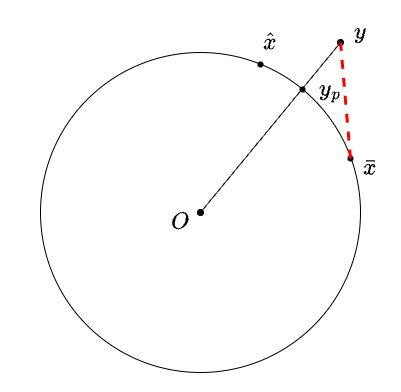

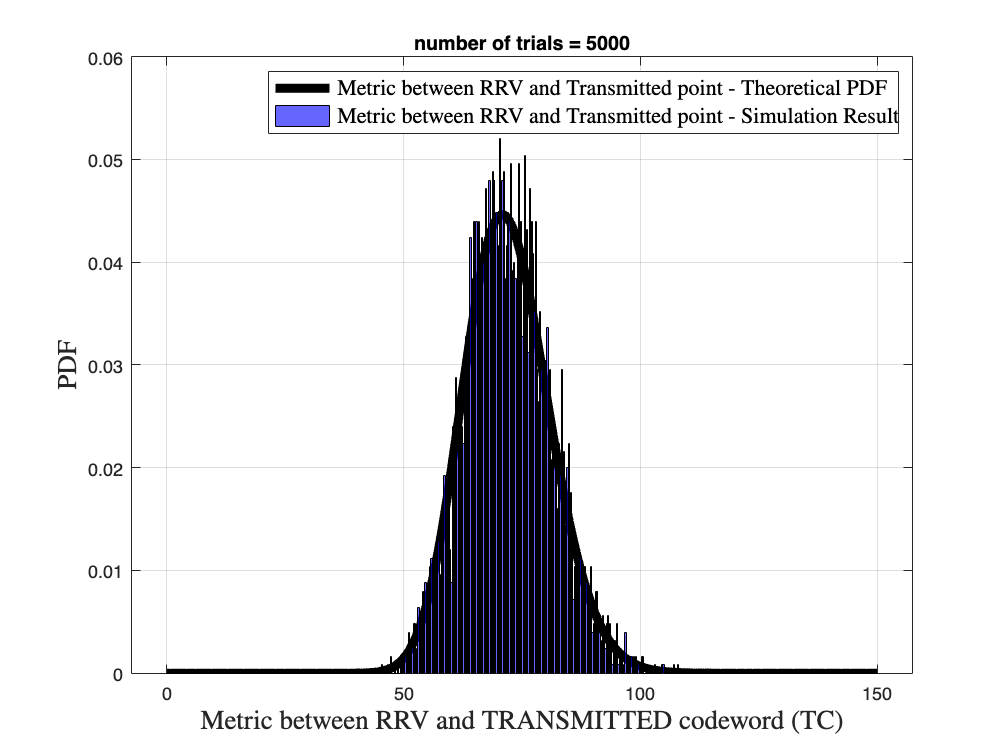

displaying_metric = RRVtoTransmitted_Metric;

number_of_trials        = length(displaying_metric);
edges                   = 0:0.25:150;
number_of_elements      = 128;
SNR_dB                  = 2.5;
SNR                     = 10.^(SNR_dB./10);
noise_var               = 1./SNR;

% Reference
x_values    = linspace(0, 150, 400);
k           = number_of_elements ./ 2;
theta       = 2 .* noise_var;
gamma_pdf   = gampdf(x_values, k, theta);    %  symbols pdf

figure(1);
plot(x_values, gamma_pdf, 'k', 'LineWidth', 5, 'DisplayName', 'Metric between RRV and Transmitted point - Theoretical PDF');
hold on;

% Result
histogram(displaying_metric, edges, 'Normalization', 'pdf', 'FaceColor', 'blue', 'EdgeColor', 'black', 'DisplayName', 'Metric between RRV and Transmitted point - Simulation Result');

% plot
xlabel('Metric between RRV and TRANSMITTED codeword (TC)', 'FontSize', 15, 'Interpreter', 'latex');
ylabel('PDF', 'FontSize', 15, 'Interpreter', 'latex');
title(sprintf('number of trials = %d', number_of_trials));
legend('FontSize', 12, 'Interpreter', 'latex');
grid on;
hold off;

## **Raw received value to Decoded Codeword Listsize vs. RRV to Transmitted Codeword Metric**

Listsize recorded here is the first ELF-TBCC codeword.

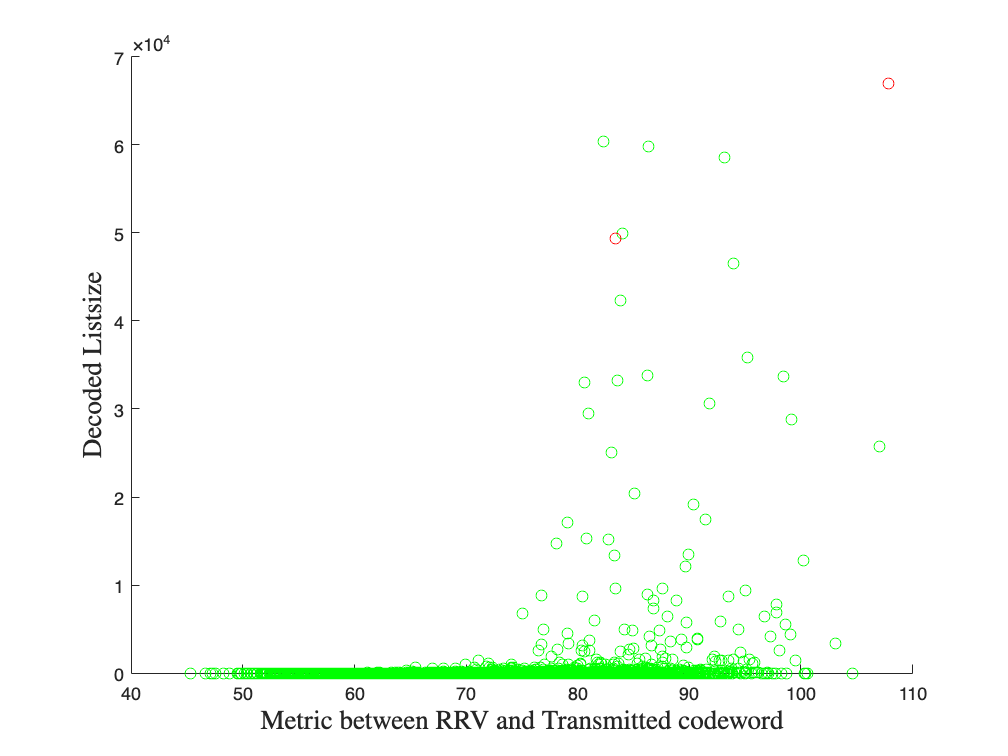

nonLSE_samples_idx  = RRVtoDecoded_Type ~= 1;
nonLSE_samples_type = RRVtoDecoded_Type(nonLSE_samples_idx);

displaying_metric   = RRVtoTransmitted_Metric(nonLSE_samples_idx);
displaying_listsize = RRVtoDecoded_Listsize(nonLSE_samples_idx);

figure();
scatter(displaying_metric(nonLSE_samples_type==0), displaying_listsize(nonLSE_samples_type==0), 'g');
hold on;
scatter(displaying_metric(nonLSE_samples_type==2), displaying_listsize(nonLSE_samples_type==2), 'r');
hold off;
xlabel("Metric between RRV and Transmitted codeword", "FontSize", 15, "Interpreter", 'latex');
ylabel("Decoded Listsize", "FontSize", 15, "Interpreter", 'latex');

## **Raw received value to Decoded Codeword Listsize vs. RRV to Decoded Codeword Metric**

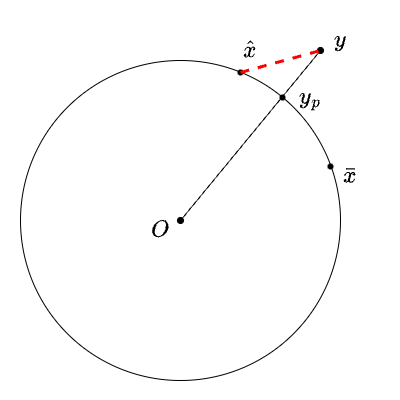

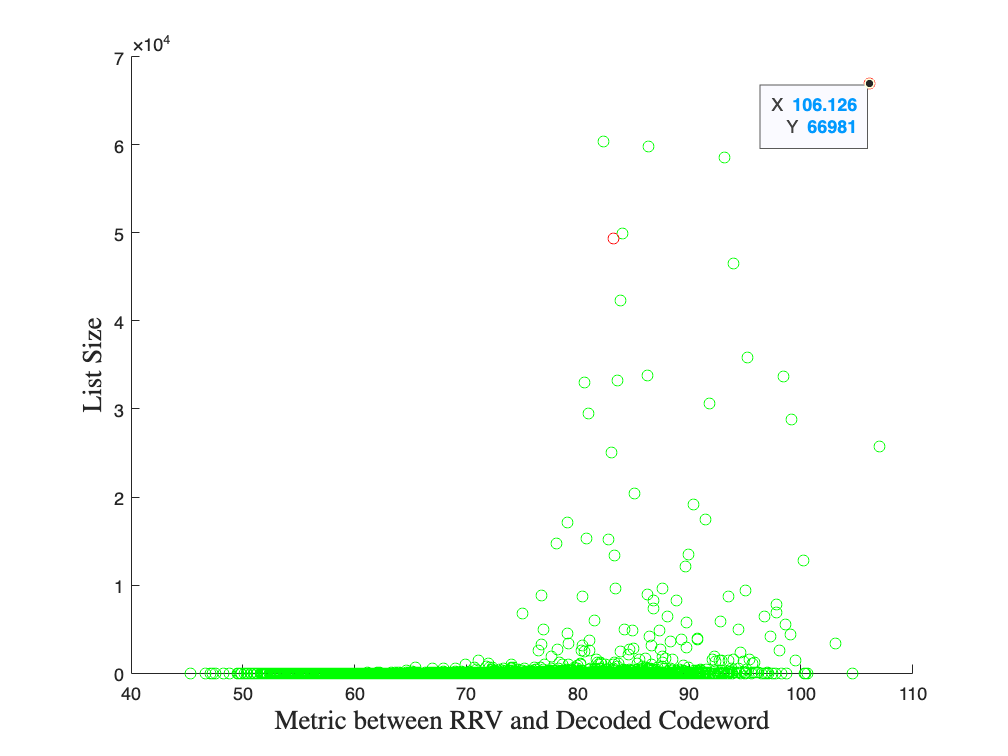

displaying_type     = RRVtoDecoded_Type;
nonLSE_samples_idx  = displaying_type ~= 1;
nonLSE_samples_type = RRVtoDecoded_Type(nonLSE_samples_idx);

displaying_listsize = RRVtoDecoded_Listsize(nonLSE_samples_idx);
displaying_metric   = RRVtoDecoded_Metric(nonLSE_samples_idx);

figure(3);

scatter(displaying_metric(nonLSE_samples_type==0), displaying_listsize(nonLSE_samples_type==0), 'g');
hold on;
scatter(displaying_metric(nonLSE_samples_type==2), displaying_listsize(nonLSE_samples_type==2), 'r');
hold off;
xlabel("Metric between RRV and Decoded Codeword", 'FontSize', 15, 'Interpreter', 'latex');
ylabel("List Size", 'FontSize', 15, 'Interpreter', 'latex');

ax = gca;
chart = ax.Children(1);
datatip(chart,85,9.331e+04);

## Projected Received Value to Transmitted Point Metric

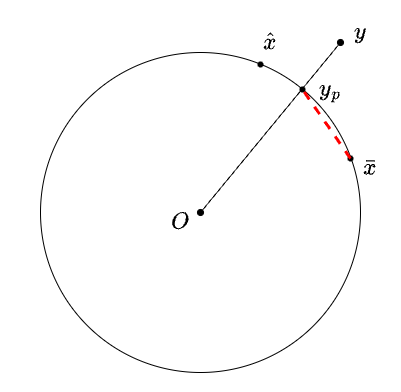

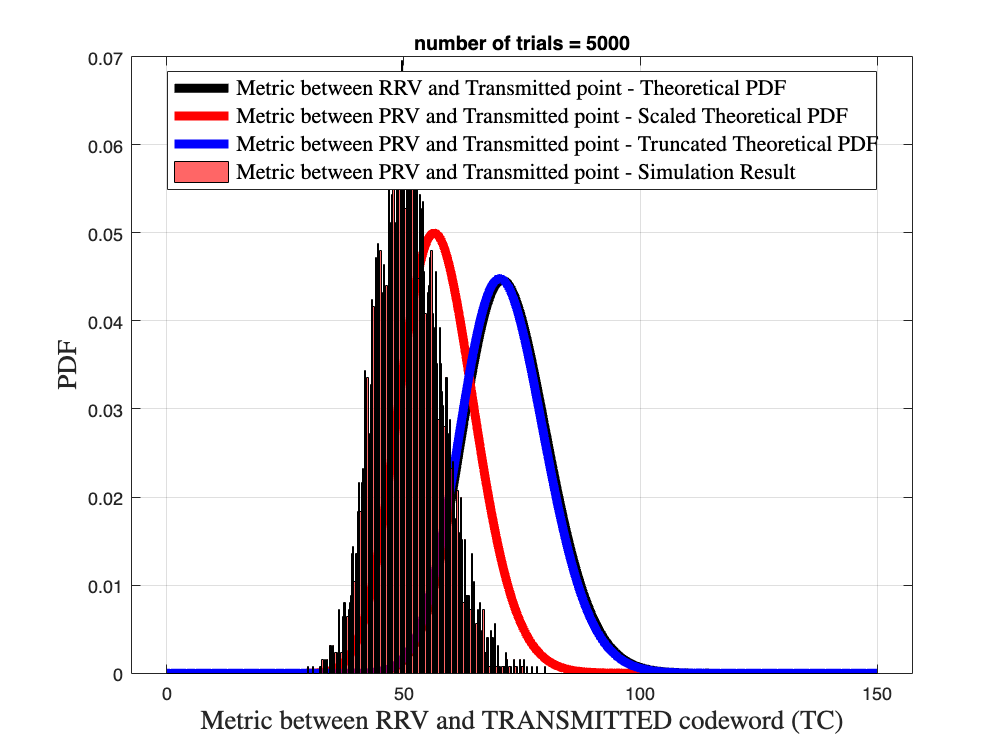

displaying_metric = PRVtoTransmitted_Metric;

number_of_trials        = length(displaying_metric);
edges                   = 0:0.25:150;
number_of_elements      = 128;
SNR_dB                  = 2.5;
SNR                     = 10.^(SNR_dB./10);
noise_var               = 1./SNR;

% Ref
x_values    = linspace(0, 150, 400);
k           = number_of_elements ./ 2;
theta       = 2 .* noise_var;
gamma_pdf   = gampdf(x_values, k, theta);    %  symbols pdf

% Ref2: Shifted gamma
scale       = sqrt(128)./sqrt(199.968);
k_new       = scale .* k;
gamma_pdf_scaled = gampdf(x_values, k_new, theta);

% Ref3: Truncated radial noise
gamma_pdf_truncated = gampdf(x_values, k-0.5, theta);

figure(2);
plot(x_values, gamma_pdf, 'k', 'LineWidth', 5, 'DisplayName', 'Metric between RRV and Transmitted point - Theoretical PDF');
hold on;
plot(x_values, gamma_pdf_scaled, 'r', 'LineWidth', 5, 'DisplayName', 'Metric between PRV and Transmitted point - Scaled Theoretical PDF');
plot(x_values, gamma_pdf_truncated, 'b', 'LineWidth', 5, 'DisplayName', 'Metric between PRV and Transmitted point - Truncated Theoretical PDF');

% Res
histogram(displaying_metric, edges, 'Normalization', 'pdf', 'FaceColor', 'red', 'EdgeColor', 'black', 'DisplayName', 'Metric between PRV and Transmitted point - Simulation Result');

% plot
xlabel('Metric between RRV and TRANSMITTED codeword (TC)', 'FontSize', 15, 'Interpreter', 'latex');
ylabel('PDF', 'FontSize', 15, 'Interpreter', 'latex');
title(sprintf('number of trials = %d', number_of_trials));
legend('FontSize', 12, 'Interpreter', 'latex', 'Location','north');
grid on;
hold off;

In the above graph, we show the theoretical curve of metric between RRV and Transmitted Point in black and histogram of metric PRV to Transmitted Point in red. As expected, the red histogram has a smaller mean than RRV to Transmitted.

## Projected Received Value (PRV) to Decoded Codeword List size vs. PRV to Transmitted Metric

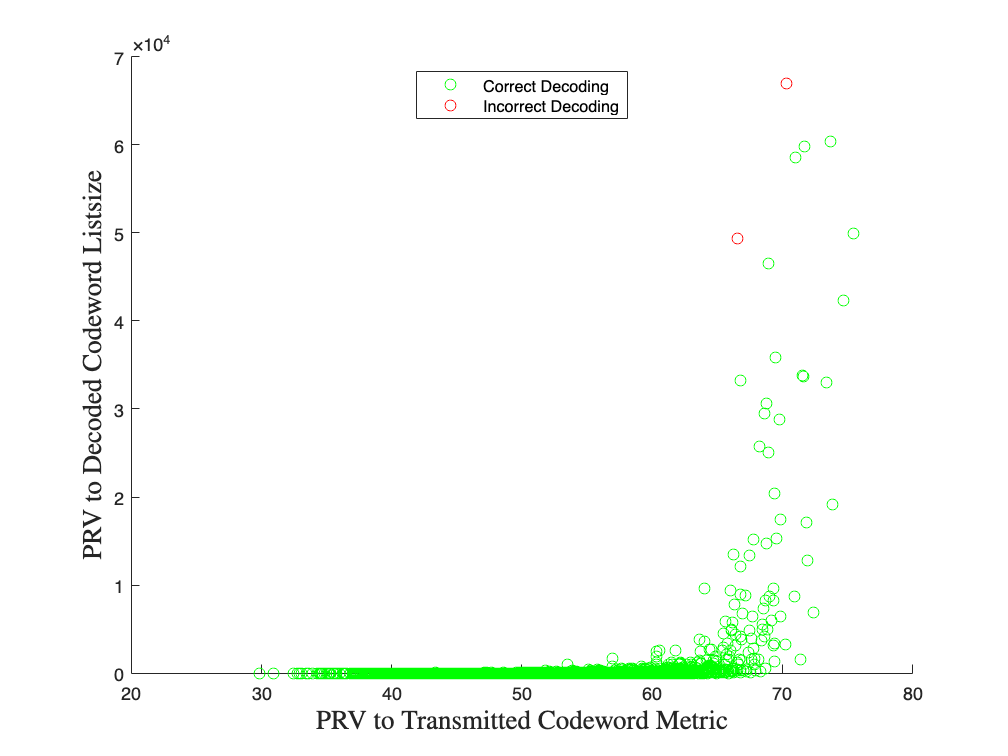

nonLSE_samples_idx  = PRVtoDecoded_Type ~= 1;
nonLSE_samples_type = PRVtoDecoded_Type(nonLSE_samples_idx);

displaying_metric   = PRVtoTransmitted_Metric(nonLSE_samples_idx);
displaying_listsize = PRVtoDecoded_Listsize(nonLSE_samples_idx);

figure();
scatter(displaying_metric(nonLSE_samples_type == 0), displaying_listsize(nonLSE_samples_type == 0), 'g', DisplayName="Correct Decoding");
hold on;
scatter(displaying_metric(nonLSE_samples_type == 2), displaying_listsize(nonLSE_samples_type == 2), 'r', DisplayName="Incorrect Decoding");
hold off;
% ylim([0, 10]);
xlabel("PRV to Transmitted Codeword Metric", "FontSize", 15, "Interpreter", 'latex');
ylabel("PRV to Decoded Codeword Listsize", "FontSize", 15, "Interpreter", 'latex');
legend(location="north");

## **Projected received value to Decoded Codeword Listsize vs. PRV to Decoded Codeword Metric**

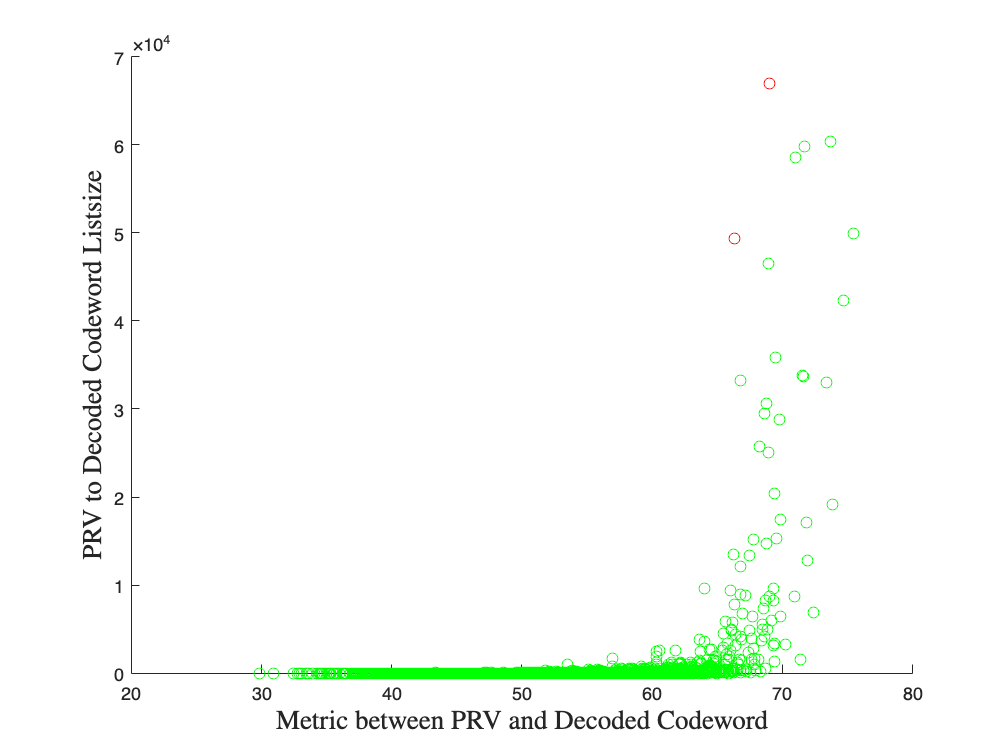

displaying_type     = PRVtoDecoded_Type;
nonLSE_samples_idx  = displaying_type ~= 1;
nonLSE_samples_type = PRVtoDecoded_Type(nonLSE_samples_idx);

displaying_listsize = PRVtoDecoded_Listsize(nonLSE_samples_idx);
displaying_metric   = PRVtoDecoded_Metric(nonLSE_samples_idx);

figure(3);

scatter(displaying_metric(nonLSE_samples_type==0), displaying_listsize(nonLSE_samples_type==0), 'g');
hold on;
scatter(displaying_metric(nonLSE_samples_type==2), displaying_listsize(nonLSE_samples_type==2), 'r');
hold off;
xlabel("Metric between PRV and Decoded Codeword", 'FontSize', 15, 'Interpreter', 'latex');
ylabel("PRV to Decoded Codeword Listsize", 'FontSize', 15, 'Interpreter', 'latex');

## RRV Jump to PRV

% pick a few samples where
nonLSE_samples_idx  = PRVtoDecoded_Type ~= 1;
nonLSE_samples_RRV_metric = RRVtoTransmitted_Metric(nonLSE_samples_idx);
nonLSE_samples_PRV_metric = PRVtoTransmitted_Metric(nonLSE_samples_idx);


picked_large_RRVtoTransmitted_samples_idx       = nonLSE_samples_RRV_metric > 100;
picked_large_RRVtoTransmitted_samples_metric    = nonLSE_samples_RRV_metric(picked_large_RRVtoTransmitted_samples_idx);
picked_large_PRVtoTransmitted_samples_metric    = nonLSE_samples_PRV_metric(picked_large_RRVtoTransmitted_samples_idx);
RRVtoPRV_Difference = picked_large_RRVtoTransmitted_samples_metric - picked_large_PRVtoTransmitted_samples_metric;

picked_large_RRVtoTransmitted_samples_listsize  = PRVtoDecoded_Listsize(picked_large_RRVtoTransmitted_samples_idx);



for idx = 1:length(picked_large_PRVtoTransmitted_samples_metric)
    result = sprintf("RRVtoTransmitted Metric: %f ----> PRVtoTransmitted Metric: %f \n", picked_large_RRVtoTransmitted_samples_metric(idx), ...
                                                                                picked_large_PRVtoTransmitted_samples_metric(idx));
    p1 = [picked_large_RRVtoTransmitted_samples_metric(idx), picked_large_RRVtoTransmitted_samples_listsize(idx)];
    p2 = [picked_large_PRVtoTransmitted_samples_metric(idx), picked_large_RRVtoTransmitted_samples_listsize(idx)];

    display(result);
end

result =     "RRVtoTransmitted Metric: 107.003000 ----> PRVtoTransmitted Metric: 68.256900 
     "


result =     "RRVtoTransmitted Metric: 100.190000 ----> PRVtoTransmitted Metric: 71.892500 
     "


result =     "RRVtoTransmitted Metric: 100.423000 ----> PRVtoTransmitted Metric: 57.102200 
     "


result =     "RRVtoTransmitted Metric: 103.092000 ----> PRVtoTransmitted Metric: 65.763400 
     "


result =     "RRVtoTransmitted Metric: 100.306000 ----> PRVtoTransmitted Metric: 59.760300 
     "


result =     "RRVtoTransmitted Metric: 107.885000 ----> PRVtoTransmitted Metric: 70.313800 
     "


result =     "RRVtoTransmitted Metric: 100.621000 ----> PRVtoTransmitted Metric: 59.023000 
     "


result =     "RRVtoTransmitted Metric: 104.629000 ----> PRVtoTransmitted Metric: 53.103500 
     "


result =     "RRVtoTransmitted Metric: 105.423000 ----> PRVtoTransmitted Metric: 65.678500 
     "


result =     "RRVtoTransmitted Metric: 101.563000 ----> PRVtoTransmitted Metric: 68.017500 
     "


result =     "RRVtoTransmitted Metric: 112.733000 ----> PRVtoTransmitted Metric: 67.831700 
     "


result =     "RRVtoTransmitted Metric: 100.555000 ----> PRVtoTransmitted Metric: 61.169400 
     "


result =     "RRVtoTransmitted Metric: 105.599000 ----> PRVtoTransmitted Metric: 68.365100 
     "


result =     "RRVtoTransmitted Metric: 104.074000 ----> PRVtoTransmitted Metric: 66.593300 
     "


result =     "RRVtoTransmitted Metric: 101.262000 ----> PRVtoTransmitted Metric: 70.849100 
     "


result =     "RRVtoTransmitted Metric: 100.568000 ----> PRVtoTransmitted Metric: 60.611000 
     "


result =     "RRVtoTransmitted Metric: 100.371000 ----> PRVtoTransmitted Metric: 68.377400 
     "


result =     "RRVtoTransmitted Metric: 101.525000 ----> PRVtoTransmitted Metric: 56.827300 
     "


result =     "RRVtoTransmitted Metric: 103.572000 ----> PRVtoTransmitted Metric: 56.761700 
     "


result =     "RRVtoTransmitted Metric: 100.823000 ----> PRVtoTransmitted Metric: 59.221700 
     "


result =     "RRVtoTransmitted Metric: 104.138000 ----> PRVtoTransmitted Metric: 60.739000 
     "


result =     "RRVtoTransmitted Metric: 109.483000 ----> PRVtoTransmitted Metric: 62.945700 
     "


result =     "RRVtoTransmitted Metric: 101.384000 ----> PRVtoTransmitted Metric: 61.648600 
     "


result =     "RRVtoTransmitted Metric: 104.723000 ----> PRVtoTransmitted Metric: 61.647400 
     "


result =     "RRVtoTransmitted Metric: 101.938000 ----> PRVtoTransmitted Metric: 61.181400 
     "


result =     "RRVtoTransmitted Metric: 103.405000 ----> PRVtoTransmitted Metric: 68.495600 
     "


result =     "RRVtoTransmitted Metric: 100.105000 ----> PRVtoTransmitted Metric: 70.613600 
     "


result =     "RRVtoTransmitted Metric: 102.672000 ----> PRVtoTransmitted Metric: 60.625700 
     "


result =     "RRVtoTransmitted Metric: 100.012000 ----> PRVtoTransmitted Metric: 49.184100 
     "


result =     "RRVtoTransmitted Metric: 102.451000 ----> PRVtoTransmitted Metric: 69.725700 
     "


result =     "RRVtoTransmitted Metric: 101.531000 ----> PRVtoTransmitted Metric: 64.621000 
     "


result =     "RRVtoTransmitted Metric: 100.711000 ----> PRVtoTransmitted Metric: 68.040500 
     "


result =     "RRVtoTransmitted Metric: 107.890000 ----> PRVtoTransmitted Metric: 65.814900 
     "


## **Finding the threshold for a fixed erasure probability**

threshold = 1e-4;
gamma_cdf = gamcdf(x_values, k, theta);

figure(2);
semilogy(x_values, 1-gamma_cdf, 'LineWidth', 2);
hold on;
yline(threshold, 'LineWidth', 2, 'Color', 'k');
hold off;
grid on;
xlabel('Threshold Metric', 'FontSize', 15);
ylabel('$P(Erasures)$', 'FontSize', 15, 'Interpreter', 'latex');




% % % max_listsize = 1e4, 
% % listsize = load('../output/listsize.txt');
% % metric = load('../output/metric.txt');
% % decoding_type = load('../output/decodingType.txt');
% % correct_metric = load('../output/SBCMetric.txt');
% % 
% % correct_indices = decoding_type == 0; % decoded = transmitted
% % erasure_indices = decoding_type == 1; % erased
% % incorrect_indices = decoding_type == 2; % decoded != transmitted
% % 
% % 
% % 
% % % plot
% % figure();
% % scatter(correct_metric, listsize(correct_indices), 'g', 'DisplayName', 'Correct decoding');
% % hold on;
% % scatter(metric(erasure_indices), listsize(erasure_indices), 'b', 'DisplayName', 'Erasures');
% % scatter(metric(incorrect_indices), listsize(incorrect_indices), 'r', 'DisplayName', 'Incorrect decoding');
% % xlabel('$|$ received metric - decoded metric $|$', 'FontSize', 18, 'Interpreter', 'latex');
% % ylabel('listsize', 'FontSize', 18); 
% % set(gca,'yscale','log')
% % legend();